# **IO324 - Analog Loopback**

The IO324 I/O module is a fast, sequential sampling 16-bit analog input and output module, complete with dedicated Simulink® driver blocks. This I/O module also contains digital pins which however are not covered by this example.

This example demonstrates the analog part of an IO324 module, which offers DAC signal generation and ADC measurement functionality. The focus is to demonstrate the setup where the IO324 module generates user-defined analog output signals on the DAC and measures them with the ADCs. This example uses the approach of model sample-based DAC value generation and ADC measurement.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO324 I/O module installed

- A Speedgoat configuration file for the IO324 module. Every IO324 configuration file always contains analog functionality

- Connector cable from the I/O module to the terminal boards

- 1x 50-pin terminal board with jumper wires (only the analog terminal is needed)

- Optional: Multimeter to measure the DAC voltages

### Test Setup

Connect the IO324 modules with the analog cable to a 50-pin terminal board, locate the DAC channels 1-8 and connect them to analog inputs 1 / 3 / 9 / 11 / 17 / 19 / 25 / 27. Note that the IO324 ADC channels can be switched between single-ended and differential ADC measurement. Analog inputs 2 / 4 / 10 / 12 / 18 / 20 / 26 / 28 will therefore be connected to GND as well.

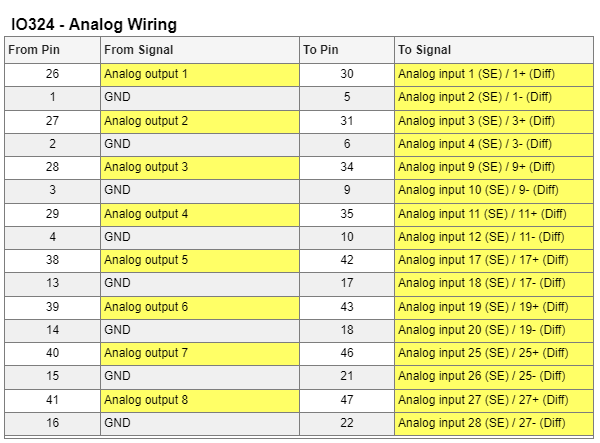

[IO324 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_200k_pin_mapping): please note that only the analog I/O of terminal board 2 are relevant for this example.

## Initialize and Open the Simulink model

Open the Simulink model and choose your appropriate connection by commenting out the unwanted configuration block.

 
% Open Simulink model
modelName = 'sgMdl_IO324_AnalogLoopback';
open_system(modelName);
% set the model time step to 10ms
set_param(modelName, 'FixedStep', '10e-3');

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select a configuration file. This example only requires analog interfaces, which are supported by any configuration file for the IO324 by default.

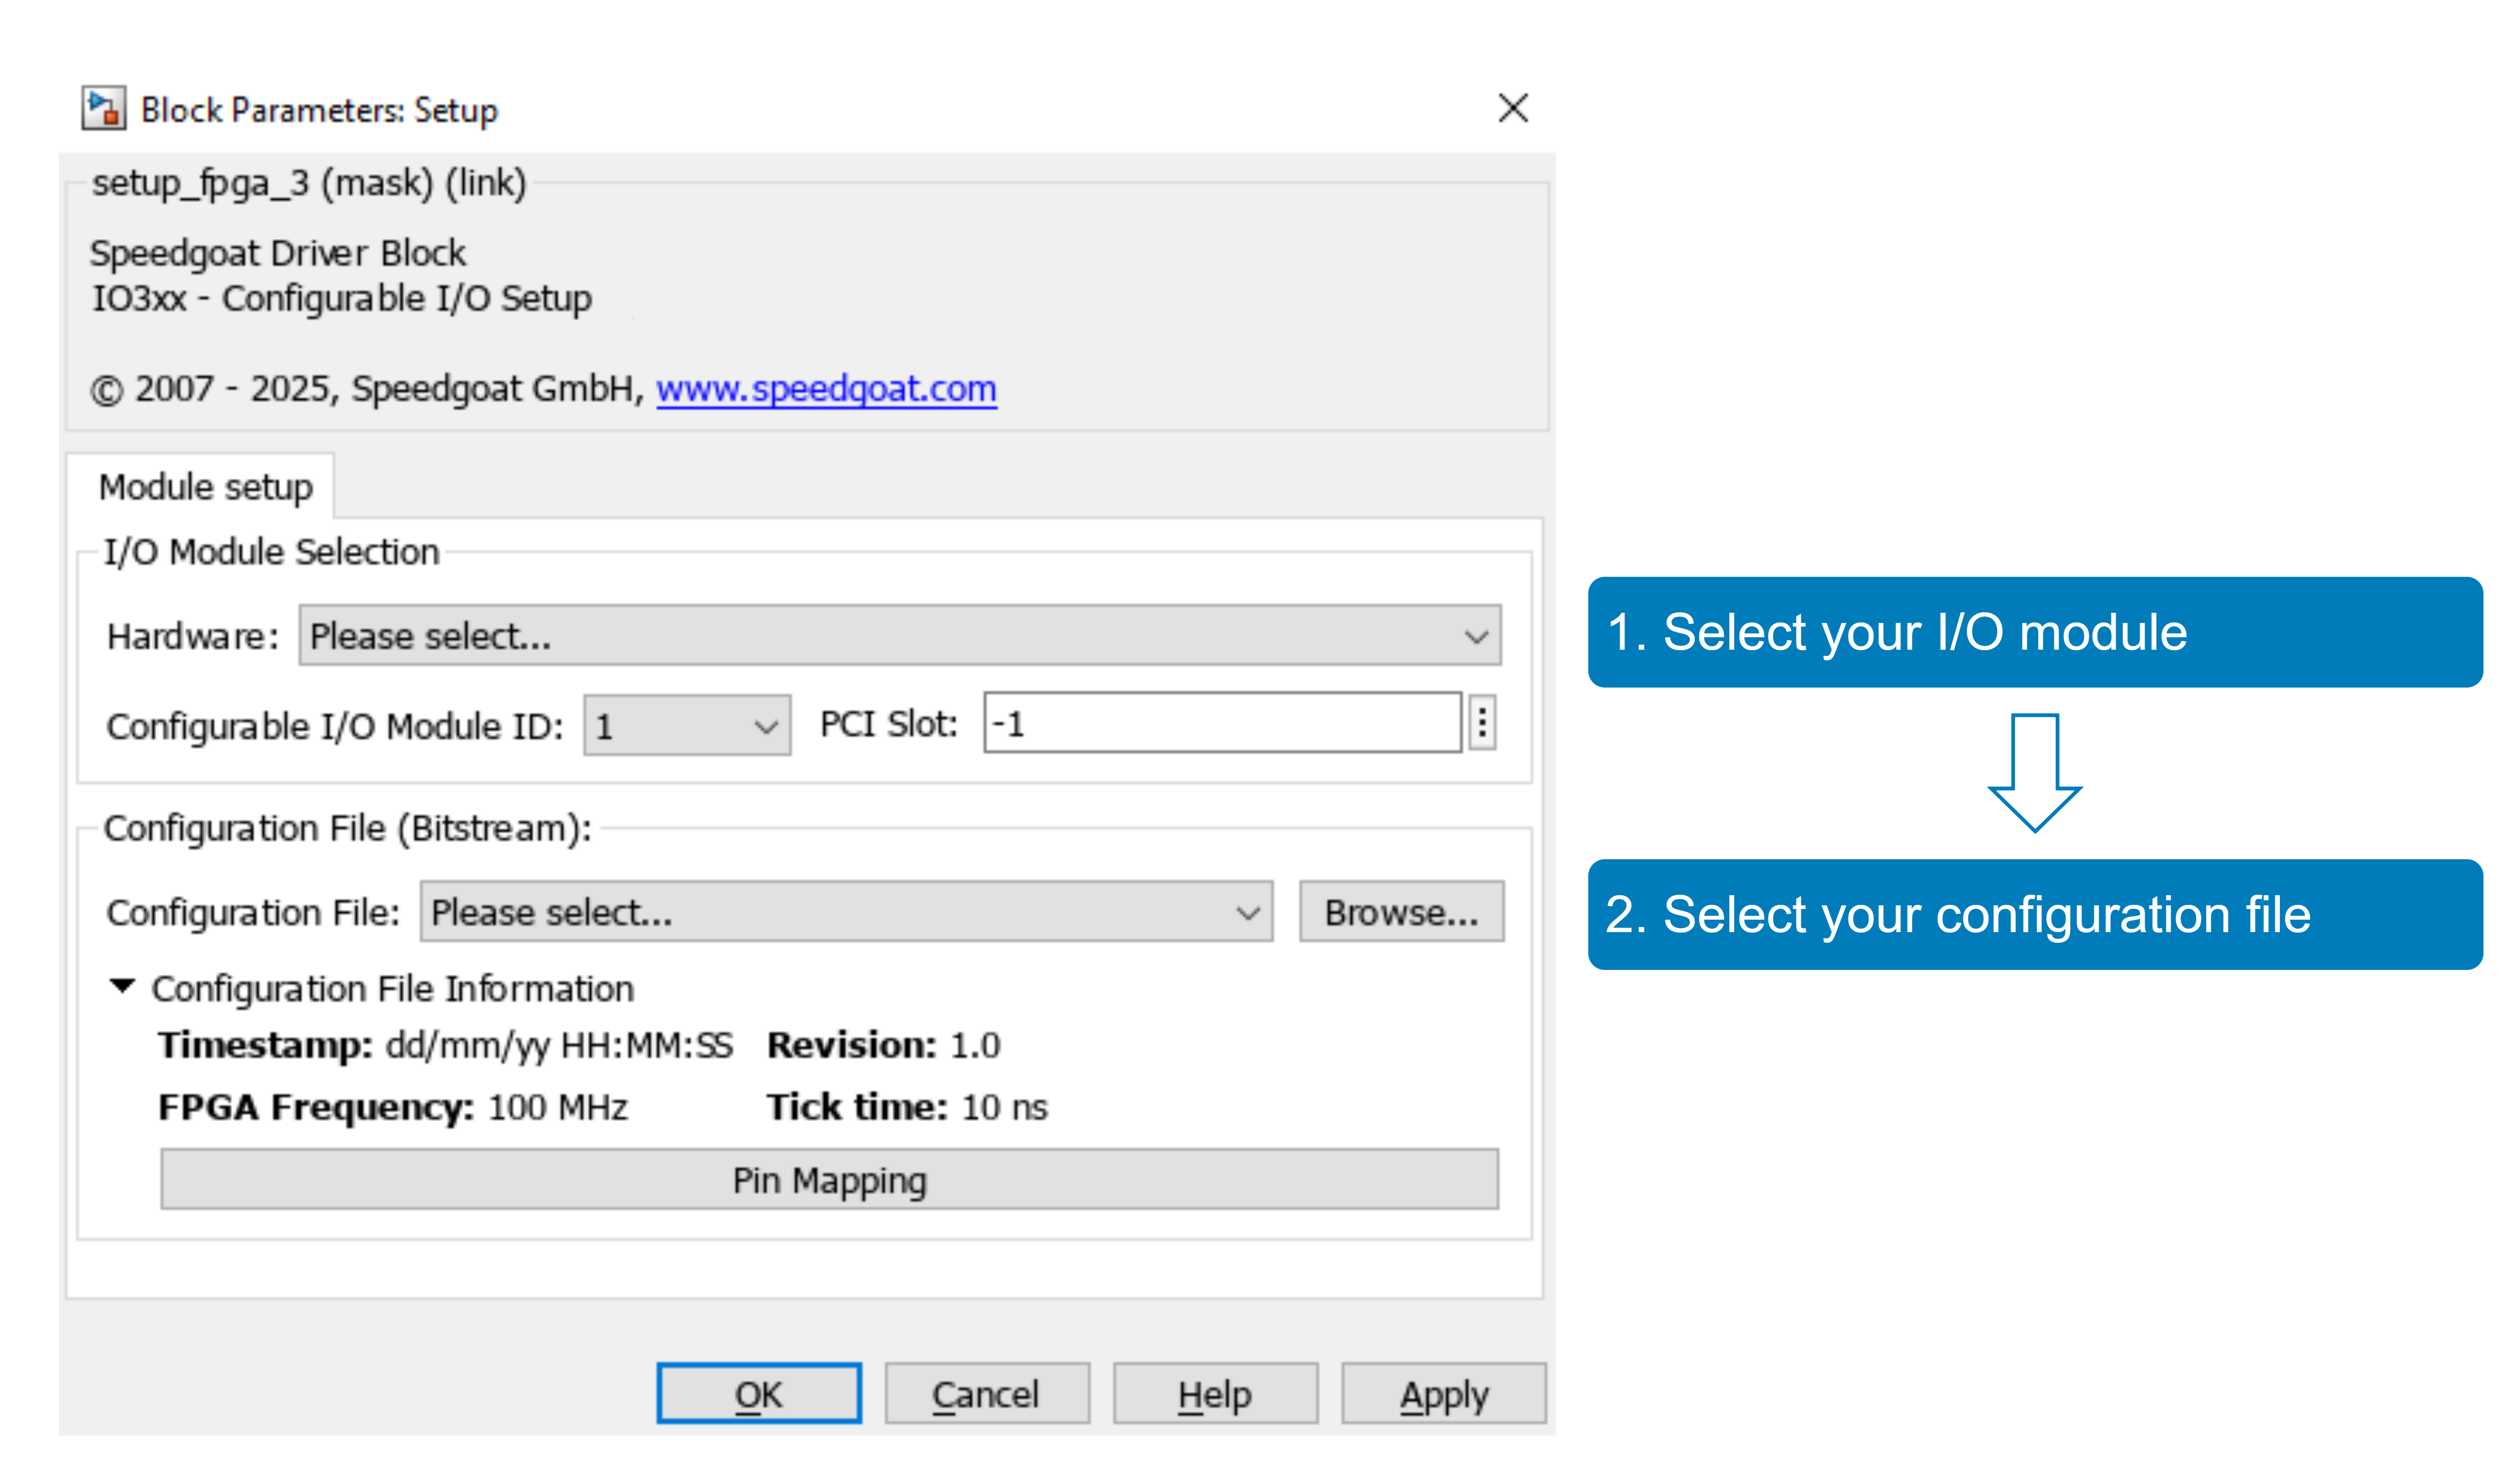

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the [IO324 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io324_200k), [IO324 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1), [IO324 Analog Input v1 ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_input_v1)and [IO324 Analog Output v1 ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_output_v1)blocks. The analog inputs and outputs of the IO324 are enabled in the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block. In this example the ADC and the DAC blocks are running in a sample-based mode.

The model generates 8 signals that are sent to the analog outputs. Each signal is a sawtooth: whilst the first signal is in the range of -10 to 0, the second signal is in the range of -9 to 1, and so on. Given the loopback wiring, the same voltage values are read again on the analog inputs.

### ADC (Analog Inputs) and DAC (Analog Outputs) Settings

To see the setup and parametrization of the ADC and DAC channels, open the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block.

#### Tab: Main

In the main tab of the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, you can see that the **ADC Sample Trigger** and **DAC Sample Trigger** parameters are both set to **Model Step**. This model therefore does an ADC conversion at each model step and then generates the next DAC output. 

#### Tab: Analog Inputs

In the **Analog Inputs** tab of the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, you can see which ADC channels are active and how they are configured. In this example, ADC channels 1 / 3 / 17 / 19 are configured as single ended, and ADC channels 9 / 11 / 25 / 27 are configured as differential. This is why the test-setup of this example requires the differential ADC negative inputs to be connected to ground.

#### Tab: Analog Outputs

In the **Analog Outputs** tab of the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, you can see which DAC channels are active and how they are configured. Note the special settings of **Initial Value [V]** and **Reset to Initial Value**. The **Initial Value [V]** will be applied on the DAC outputs every time a newly compiled model is downloaded to the target.

The channels with **Reset to Initial Value** enabled will apply the **Initial Value [V]** when the real-time application is stopped. In this example, only the DAC channels 1 / 3 / 5 / 7 are configured to reset to the initial value at model stop.

### Analog Input (ADC) and Analog Output (DAC) Blocks

Note that the [IO324 Analog Input ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_input_v1)block is set to the highest priority, to ensure the ADC conversion is done before a new DAC value is generated.

 
% Mandatory: set the Analog Input Block Priority to 1 and the Analog Output Block Priority to 2
if sg.utils.compareMatlabVersion('>', 'R2022a')
    set_param([modelName, '/IO324 Analog input'],  'priority', '1');
    set_param([modelName, '/IO324 Analog output'], 'priority', '2');
    % sorted execution order in the model
    Simulink.BlockDiagram.getExecutionOrder(modelName);
else
    warning('Priority setting not supported in this Release, you need to set manually');
end

**Note that in case your Matlab Release is 2022a or previous, you have to set the priorities manually in the model:**

- Right Clock on the model-block **IO324 Analog input**, select **Properties...** and set the **Priority:** to 1

- Right Clock on the model-block **IO324 Analog output**, select **Properties...** and set the **Priority:** to 2

- Right Click anywhere in the model and select **Other Displays -> Blocks -> Sorted Execution Order**, your model will now show the execution order of all blocks. The order execution number of the **IO324 Analog input** (prio higher) must be lower than **IO324 Analog output**

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Define and set stop-time
stoptime = 4.5; % Simulation length [s]

tg.setStopTime(stoptime);

% Start the real-time application
tg.start;
pause(stoptime+1);

## Show and Analyze the Signals

To show the measured signals, either run the following code section or click the **Data Inspector** button in the **REAL-TIME** tab in the Simulink model.

 
% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,1);         % layout with two plots

% get signals by name (signal label in Simulink)
ADC_Signal = SDIRun.getSignalsByName('ADC in');
DAC_Signal = SDIRun.getSignalsByName('DAC out');

% expand signals 
expand(ADC_Signal);
expand(DAC_Signal);

% assign DAC signals to subplot 1
plotOnSubPlot(DAC_Signal.Children(1),1,1,true);
plotOnSubPlot(DAC_Signal.Children(2),1,1,true);
plotOnSubPlot(DAC_Signal.Children(3),1,1,true);
plotOnSubPlot(DAC_Signal.Children(4),1,1,true);
plotOnSubPlot(DAC_Signal.Children(5),1,1,true);
plotOnSubPlot(DAC_Signal.Children(6),1,1,true);
plotOnSubPlot(DAC_Signal.Children(7),1,1,true);
plotOnSubPlot(DAC_Signal.Children(8),1,1,true);

% assign ADC signals to subplot 1
plotOnSubPlot(ADC_Signal.Children(1),2,1,true);
plotOnSubPlot(ADC_Signal.Children(2),2,1,true);
plotOnSubPlot(ADC_Signal.Children(3),2,1,true);
plotOnSubPlot(ADC_Signal.Children(4),2,1,true);
plotOnSubPlot(ADC_Signal.Children(5),2,1,true);
plotOnSubPlot(ADC_Signal.Children(6),2,1,true);
plotOnSubPlot(ADC_Signal.Children(7),2,1,true);
plotOnSubPlot(ADC_Signal.Children(8),2,1,true);

% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"tMin",-0.05,"tMax",4.55);   % set time span
Simulink.sdi.setSubplotLimits(1,1,"yMin",-10.5,"yMax",7.5);    % set y-zoom of channel 1
Simulink.sdi.setSubplotLimits(2,1,"yMin",-10.5,"yMax",7.5);    % set y-zoom of other channels

### Check the Results

The SDI view shows you the generated DAC output values and the measured ADC input values.

Each Signal is a sawtooth with a difference of 10 V. Channel 1 starts at -10 V, and Channel 2 starts at -9 V, and so on.

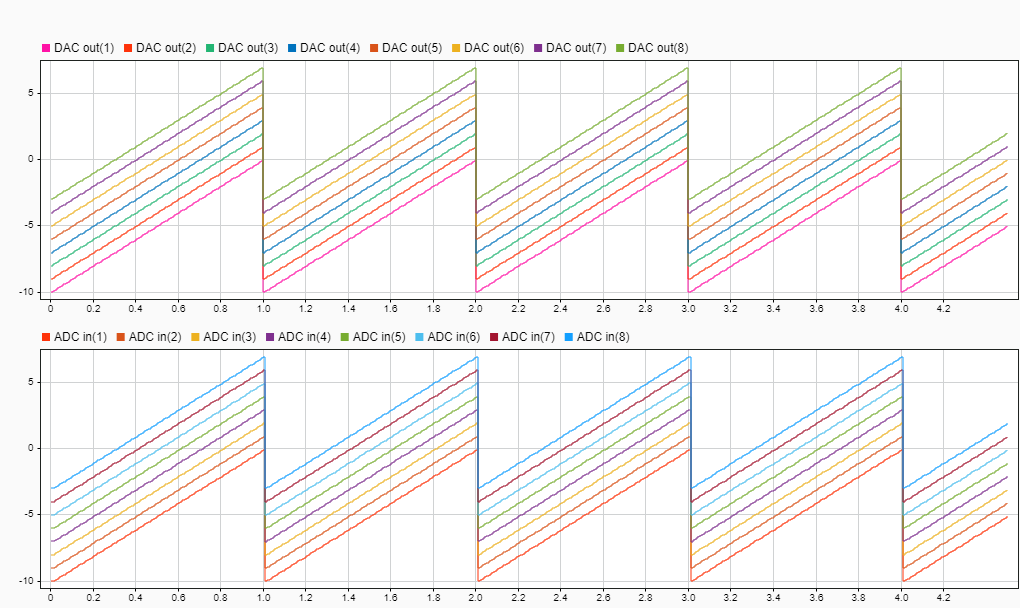

The ADC in values match the DAC out values.

Note that there is one sample step delay between the ADC out values and the DAC in values (this can be better observed by time-zooming on a point where the sawtooth finished):

 
% Zoom in around T = 1s
Simulink.sdi.setSubplotLimits(1,1,"tMin",0.8,"tMax",1.2);   % set time span

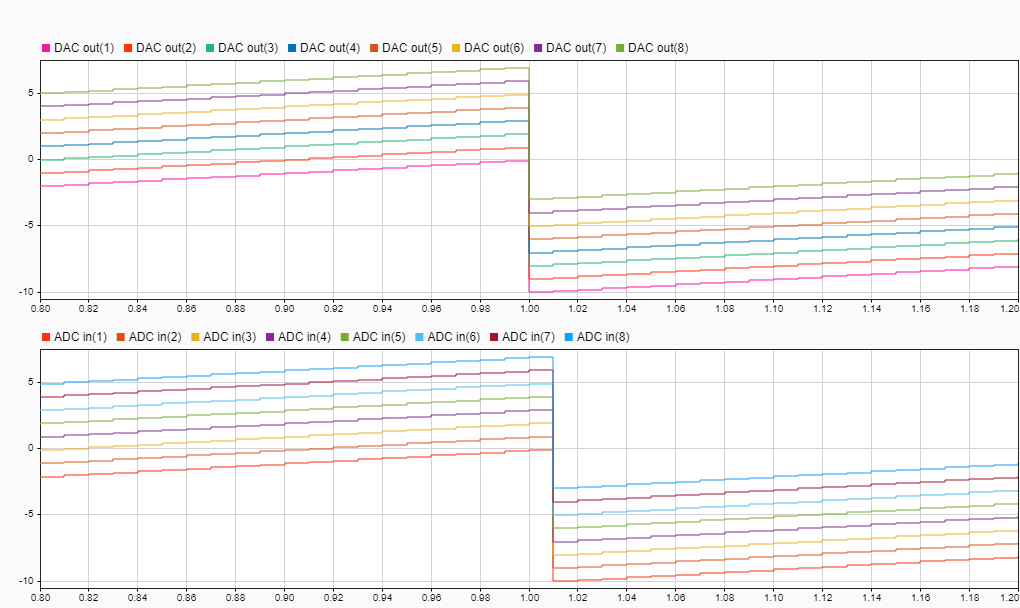

#### Measuring the DAC-Values after Model-Stop

As described, the signals for the DAC are sawteeth that restart every second. As you can see, the stop time of this example is set to 4.5 s, which is the "middle" of the sawtooth. This can also be seen by the above scope-signals at the end.

Remember that we set **Reset to Initial Value** on DAC channels 1 / 3 / 5 / 7.

Therefore, you can optionally measure the DAC outputs at the end of the simulation using a standard multimeter and manually measure the DAC signals. Regarding this example and the settings in the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, you should measure the following voltages at the DAC outputs after the model has stopped:

- DAC1: -10 V (**Reset to Initial Value** is set, **Initial Value [V]** is set to -10 V)

- DAC2:  -4 V (**Reset to Initial Value** is NOT set), -4 V is the last DAC Value at model stop

- DAC3:  -8 V (**Reset to Initial Value** is set, **Initial Value [V]** is set to -8 V)

- DAC4:  -2 V (**Reset to Initial Value** is NOT set), -2 V is the last DAC Value at model stop

- DAC5:  -6 V (**Reset to Initial Value** is set, **Initial Value [V]** is set to -6 V)

- DAC6:   0 V (**Reset to Initial Value** is NOT set), 0 V is the last DAC Value at model stop

- DAC7:  -4 V (**Reset to Initial Value** is set, **Initial Value [V]** is set to -4 V)

- DAC8:   2 V (**Reset to Initial Value** is NOT set), 2 V is the last DAC Value at model stop

Another way to see the outputs at the end of the simulation is to re-launch the same model and check the measured data. Note that after a model has been built, downloaded and run for the first time, all DAC values are set to their initial values. If you just re-run the model again, the DAC outputs keep their last value. Since the priorities in these example models are defined so that the analog inputs (ADC) are measured before a new analog output (DAC) is generated, the first measured analog input will be equal to the last analog output of the previous run.

The following code simply re-runs the example model and displays the measured data for the first samples only:

 
% Just Re-load and Re-start the model again
tg.load(modelName);
stoptime = 4.5; % Simulation length [s]
tg.setStopTime(stoptime);
tg.start;
pause(stoptime+1);

% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';
% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,1);         % layout with two plots
% get signals by name (signal label in Simulink)
ADC_Signal = SDIRun.getSignalsByName('ADC in');
DAC_Signal = SDIRun.getSignalsByName('DAC out');
% expand signals 
expand(ADC_Signal);
expand(DAC_Signal);
% assign DAC signals to subplot 1
plotOnSubPlot(DAC_Signal.Children(1),1,1,true);
plotOnSubPlot(DAC_Signal.Children(2),1,1,true);
plotOnSubPlot(DAC_Signal.Children(3),1,1,true);
plotOnSubPlot(DAC_Signal.Children(4),1,1,true);
plotOnSubPlot(DAC_Signal.Children(5),1,1,true);
plotOnSubPlot(DAC_Signal.Children(6),1,1,true);
plotOnSubPlot(DAC_Signal.Children(7),1,1,true);
plotOnSubPlot(DAC_Signal.Children(8),1,1,true);
% assign ADC signals to subplot 1, plot even signals with lineWidth 4px
plotOnSubPlot(ADC_Signal.Children(1),2,1,true);
ADC_Signal.Children(2).LineWidth = 4;
plotOnSubPlot(ADC_Signal.Children(2),2,1,true);
plotOnSubPlot(ADC_Signal.Children(3),2,1,true);
ADC_Signal.Children(4).LineWidth = 4;
plotOnSubPlot(ADC_Signal.Children(4),2,1,true);
plotOnSubPlot(ADC_Signal.Children(5),2,1,true);
ADC_Signal.Children(6).LineWidth = 4;
plotOnSubPlot(ADC_Signal.Children(6),2,1,true);
plotOnSubPlot(ADC_Signal.Children(7),2,1,true);
ADC_Signal.Children(8).LineWidth = 4;
plotOnSubPlot(ADC_Signal.Children(8),2,1,true);
% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"yMin",-10.5,"yMax",7.5);     % set y-zoom of channel 1
Simulink.sdi.setSubplotLimits(2,1,"yMin",-10.5,"yMax",7.5);     % set y-zoom of other channels
Simulink.sdi.setSubplotLimits(1,1,"tMin",-0.05,"tMax",0.55);    % set time span
% set cursor on Position 0
Simulink.sdi.setNumCursors(1);
Simulink.sdi.setCursorPositions('left',0);

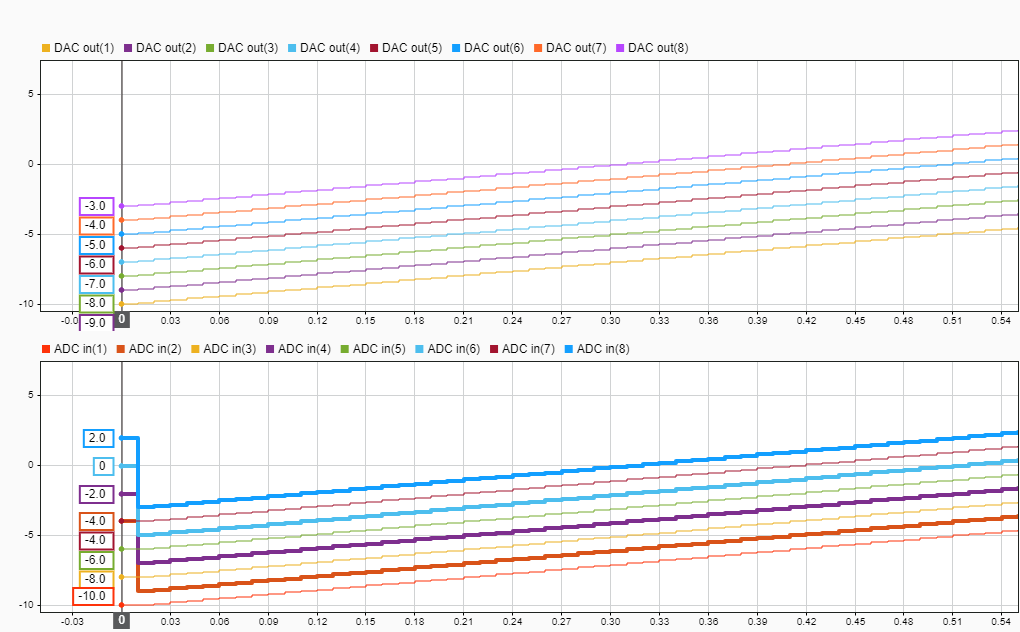

On the measured signals, you can now see that the analog input values that are connected to the even-numbered analog outputs (e.g. DAC ch2, DAC ch4, etc. (thick lines)) are equal to the values from the end of the previous simulation run on the first sample step.

The odd numbered analog outputs (e.g. DAC1, DAC3 etc. (thin lines)) have been reset to their **Initial Values** at the end of the previous simulation run. Consequently, the measured values on the first sample step are equal to the **Initial Values**.

## Additional References

- [IO324 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io324_200k)

- [Analog IO324](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io324_200k)